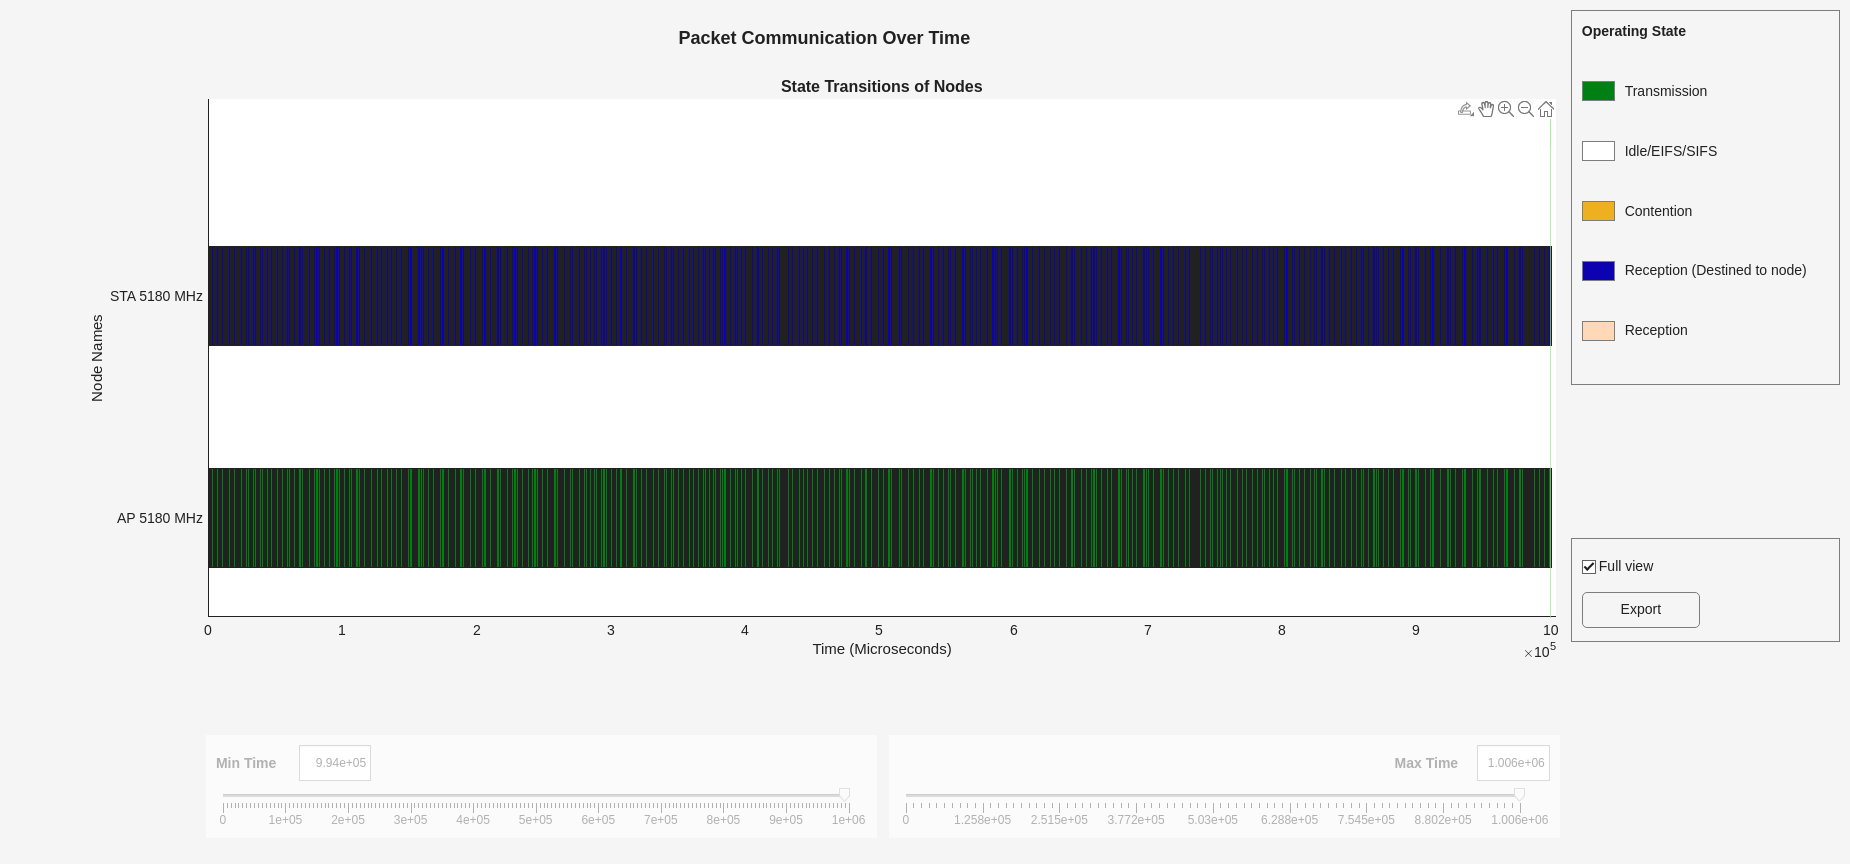

% --[Check if the Comm Toolbox is installed]--
wirelessnetworkSupportPackageCheck;

% --[Configure Simulation Parameters]--

% Set the seed to 1 : effects backoff counter selection (L2), packet reception success (L1)
rng(1,"combRecursive");
% Set the simulation time (in seconds)
simulationTime = 1;
% To visualize a live state transition for all the nodes
enablePacketVisualization = true;
% To view the node perfornance visualization
enableNodePerformancePlot = true;
% Modeling full MAC and PHY processing
MACFrameAbstraction = false;
PHYAbstractionMethod = "none";
% Packet Capture for analysis
capturePacketsFlag = true;

packetSize = 1500; % in bytes
packetArrivalRate = 800; % packets per second
dataRate = (packetArrivalRate * packetSize * 8)/1000; % Compute DataRate in Kbps
bufferSize = 500;

% --[Configure WLAN Scenario]--
% Initialize the Wireless Network Simulator
networkSimulator = wirelessNetworkSimulator.init;
% Nodes Configuration
accessPointCfg = wlanDeviceConfig(Mode="AP",MCS=1,TransmitPower=20, TransmissionFormat="HT-Mixed", TransmitQueueSize=bufferSize); % AP device configuration
%%% % To configure 802.11be, set the TransmissionFormat
%%% accessPointCfg = wlanDeviceConfig(Mode="AP",TransmissionFormat="EHT-SU",MCS=13);
stationCfg = wlanDeviceConfig(Mode="STA",MCS=1,TransmitPower=20, TransmissionFormat="HT-Mixed", TransmitQueueSize=bufferSize);    % STA device configuration
% Nodes Creation
accessPoint = wlanNode(Name="AP", ...
    Position=[10 0 0], ...
    DeviceConfig=accessPointCfg, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);

station = wlanNode(Name="STA", ...
    Position=[20 0 0], ...
    DeviceConfig=stationCfg, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);
% Create WLAN network
nodes = [accessPoint station];
% Verify if all nodes are configured properly
hCheckWLANNodesConfiguration(nodes);

% Association and Application Traffic
associateStations(accessPoint, station);

%%% % --[Configure External Application Traffic : On-Off,Video,Voice,FTP]---
%%% % To generate an On-Off application traffic
trafficSourceDL = networkTrafficOnOff(DataRate=dataRate,PacketSize=packetSize,OnTime=Inf,OffTime=0);
%%% trafficSourceUL = networkTrafficOnOff(DataRate=dataRate,PacketSize=packetSize,OnTime=Inf,OffTime=0);
addTrafficSource(accessPoint,trafficSourceDL,DestinationNode=station,AccessCategory=0);
%%% addTrafficSource(station,trafficSourceUL,DestinationNode=accessPoint,AccessCategory=0);
% % Wireless Channel
% channel = hSLSTGaxMultiFrequencySystemChannel(nodes)
% addChannelModel(networkSimulator, channel.ChannelFcn);

%%% % Add Mobility To Nodes : STA for example (but can be added to any node)
%%% addMobility(station)

% --[Export WLAN MAC Frames to PCAP]--
if capturePacketsFlag
    clear capturePacketsObj;                       % Clear existing helper object
    capturePacketsObj = hExportWLANPackets(nodes);
end

% --[Simulation and Results]--
% Add the nodes to the Wireless Network Simulator
addNodes(networkSimulator,nodes)
% View the state transition plot
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end
% View the node performance visualiszation
if enableNodePerformancePlot
    performancePlotObj = hVisualizePerformance(nodes,simulationTime);
end
% Run the simulator
run(networkSimulator, simulationTime);

% Retrieve the APP, MAC and PHY statistics at each node
apStats = statistics(accessPoint);
staStats = statistics(station);

% Delete the PCAP objects
if capturePacketsFlag
    delete(capturePacketsObj.PCAPObjList);
end

disp(apStats.App)

    TransmittedPackets: 801
      TransmittedBytes: 1201500
       ReceivedPackets: 0
         ReceivedBytes: 0



disp(staStats.App)

    TransmittedPackets: 0
      TransmittedBytes: 0
       ReceivedPackets: 799
         ReceivedBytes: 1198500



disp(apStats.MAC)

            TransmittedDataFrames: 800
          TransmittedPayloadBytes: 1198500
      SuccessfulDataTransmissions: 799
          RetransmittedDataFrames: 0
                TransmittedAMPDUs: 731
             TransmittedRTSFrames: 731
           TransmittedMURTSFrames: 0
             TransmittedCTSFrames: 0
           TransmittedMUBARFrames: 0
             TransmittedAckFrames: 0
        TransmittedBlockAckFrames: 0
    TransmittedBasicTriggerFrames: 0
               ReceivedDataFrames: 0
             ReceivedPayloadBytes: 0
                   ReceivedAMPDUs: 0
                ReceivedRTSFrames: 0
              ReceivedMURTSFrames: 0
                ReceivedCTSFrames: 731
              ReceivedMUBARFrames: 0
                ReceivedAckFrames: 0
           ReceivedBlockAckFrames: 730
       ReceivedBasicTriggerFrames: 0
           ReceivedFCSValidFrames: 1461
                 ReceivedFCSFails: 0
        ReceivedDelimiterCRCFails: 0



disp(staStats.MAC)

            TransmittedDataFrames: 0
          TransmittedPayloadBytes: 0
      SuccessfulDataTransmissions: 0
          RetransmittedDataFrames: 0
                TransmittedAMPDUs: 0
             TransmittedRTSFrames: 0
           TransmittedMURTSFrames: 0
             TransmittedCTSFrames: 731
           TransmittedMUBARFrames: 0
             TransmittedAckFrames: 0
        TransmittedBlockAckFrames: 730
    TransmittedBasicTriggerFrames: 0
               ReceivedDataFrames: 799
             ReceivedPayloadBytes: 1198500
                   ReceivedAMPDUs: 730
                ReceivedRTSFrames: 731
              ReceivedMURTSFrames: 0
                ReceivedCTSFrames: 0
              ReceivedMUBARFrames: 0
                ReceivedAckFrames: 0
           ReceivedBlockAckFrames: 0
       ReceivedBasicTriggerFrames: 0
           ReceivedFCSValidFrames: 1530
                 ReceivedFCSFails: 0
        ReceivedDelimiterCRCFails: 0



disp(apStats.PHY)

         TransmittedPackets: 1462
    TransmittedPayloadBytes: 1241958
            ReceivedPackets: 1461
       ReceivedPayloadBytes: 33594
             DroppedPackets: 0



disp(staStats.PHY)

         TransmittedPackets: 1461
    TransmittedPayloadBytes: 33594
            ReceivedPackets: 1461
       ReceivedPayloadBytes: 1240424
             DroppedPackets: 0

